## EventDuration

**Clear the workspace**

clearvars -except folderNames dataFolders

#### Import Data and Extract Behavioral Interval of Interest

normalized_traces = readmatrix("normalized_trace.xlsx"); 
normalized_max_noise_level = readmatrix("normalized_max_noise_level.xlsx"); 

Inactivate this section when following the data analysis workfow (ctrl+R to inactivate; ctrl+T to activate)

% start_time = 1; % put the interval of interest, unit is second
% end_time = 130;
% 
% % still need fix this part--need it no decimal
% % Extract from events matrix the behavioral interval of interest; 65.6 ms/frame

Inactivate this section when want to use manually input

start_time = readmatrix ("start_time.xlsx");
end_time = readmatrix ("end_time.xlsx");

Apply time interval to data

Traces_extracted = normalized_traces(:,floor(start_time/0.0656):floor(end_time/0.0656) - 1); 

**Using MatLab function to find peak**

eventsPeakAmplitude = cell(size(Traces_extracted,1), 1);
eventsPeakIdx = cell(size(Traces_extracted,1), 1);
eventsWidth = cell(size(Traces_extracted,1), 1);
eventsProminence = cell(size(Traces_extracted,1), 1);
eventsInverted_window_frames = cell(size(Traces_extracted,1),1);
eventsValleyValues = cell(size(Traces_extracted,1),1);
eventsValleyIdx = cell(size(Traces_extracted,1),1);
eventsMins_maxes = cell(size(Traces_extracted,1),1);

for x = 1:size(Traces_extracted,1)
    [eventsPeakAmplitude{x}, eventsPeakIdx{x}, eventsWidth{x}, eventsProminence{x}] = findpeaks(Traces_extracted(x,:),'WidthReference','halfheight');
    eventsInverted_window_frames{x} = max(Traces_extracted(x,:)) - Traces_extracted(x,:);
    [eventsValleyValues{x}, eventsValleyIdx{x}] = findpeaks(eventsInverted_window_frames{x});
    eventsMins_maxes{x} = sort([eventsPeakIdx{x}(:)', eventsValleyIdx{x}(:)']);
end

## EventWidth matrix

Below if for extracting event Amp of each neuron

%colsToDelete is for identify the index/column should be removed based on detecting threshold
colsToDelete = cell(size(eventsPeakAmplitude)); 

%Below is for extracting event amplitude based on detecting threshold
eventsPeakAmplitude_del = cell(size(eventsPeakAmplitude));

for x = 1:size(eventsPeakAmplitude,1)
    temp = cell2mat(eventsPeakAmplitude(x,1));
    colsToDelete{x} = find(temp < normalized_max_noise_level(x));
    temp(colsToDelete{x}) = [];
    eventsPeakAmplitude_del{x} = temp;
    clear temp
end

### Extracting event width (duration) of each neuron

%Below is for extracting event width based on detecting threshold
eventsWidth_del= cell(size(eventsWidth)); 

for x = 1:size(eventsWidth,1)
    temp = cell2mat(eventsWidth(x,1));
    temp(colsToDelete{x}) = [];
    eventsWidth_del{x} = temp;
    clear temp
end

% Below is for generating simple matrix of eventWidth

% First-step is to find the longest length to generate the NaN matrix
longest_trace_width = NaN(size(eventsWidth_del));%make the matrix to store the total event# of each neuron 

for x = 1:length(eventsWidth_del)
    longest_trace_width(x) = max(length(eventsWidth_del{x,1}));
end


longest_trace_widthFinal = max(longest_trace_width);%find the largest # in maxtrix

% Second-setp is to generate a NaN matrix to store the value
eventsWidthFinal = NaN(size(eventsWidth_del,1), longest_trace_widthFinal);

for x = 1:length(eventsWidth_del)
    temp = eventsWidth_del{x,1};
    temp(1,length(temp)+1:longest_trace_widthFinal) = NaN;
    eventsWidthFinal(x,:) = temp;
    clear temp
end

% Third-step is convert frame to time, 65.6 ms/frame
eventsWidthFinalTime = 65.6*(eventsWidthFinal);
Mean_duration = nanmean(eventsWidthFinalTime,2);

### **Distribution of Duration**

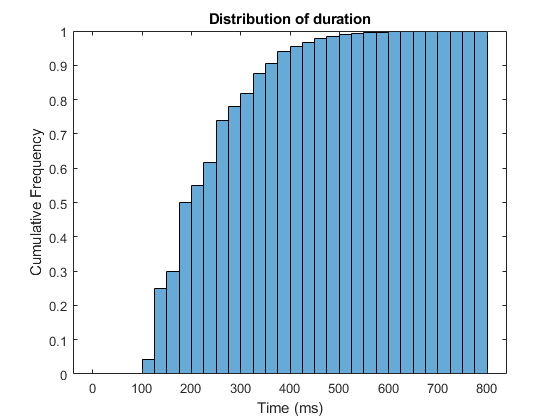

% Shows distribution of All events duration
all_duration_mat_column = eventsWidthFinalTime(:);
all_duration_mat_colum_noNaN = rmmissing(all_duration_mat_column);

figure
duration_edges= [0:25:max(all_duration_mat_colum_noNaN)]; % defined edges-- minimum edge : bin size : max edge
all_duration_distribution = histogram(all_duration_mat_colum_noNaN, duration_edges,'normalization','cdf'); % Edna: Set 0.1 for Correlation coefficient.
title('Distribution of duration');
xlabel('Time (ms)');
ylabel('Cumulative Frequency')


% Extract value from all_duration_distribution histogram
all_duration_distribution_values = all_duration_distribution.Values;

### Write Variables to Excel

writematrix(Mean_duration,'Mean Duration.xlsx');
writematrix(all_duration_distribution_values,'Distribution_Duration.xlsx');